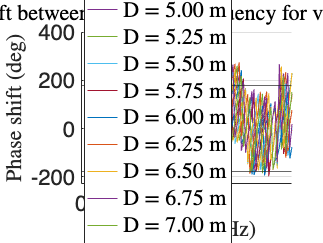

% Sweep 2-WEC spacing: 4.00 m to 7.00 m in 0.25 m increments
D_values = 4.00:0.25:7.00;


% Figure + two stacked tiles
figure('Color','w');
t = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

ax1 = nexttile; hold(ax1,'on'); grid(ax1,'on'); box(ax1,'on');  % wrapped (deg)
ax2 = nexttile; hold(ax2,'on'); grid(ax2,'on'); box(ax2,'on');  % unwrapped (deg)

for D = D_values
    % Build filename like 'hydro/2WEC_Spacing_4p25m.h5'
    D_tag   = strrep(sprintf('%.2f', D), '.', 'p');
    filename = sprintf('hydro/2WEC_Spacing_%sm.h5', D_tag);

    try
        % Load hydro data
        hydro = convh5_v2(filename);

        % Complex excitation forces
        Fex_f1 = squeeze(complex(hydro.float_up.Fex_re, hydro.float_up.Fex_im));
        Fex_f2 = squeeze(complex(hydro.float_dn.Fex_re, hydro.float_dn.Fex_im));

        % Phase shift (heave = index 3)
        phi = angle(Fex_f1(3,:)) - angle(Fex_f2(3,:));

        % Wrapped (deg) and unwrapped (deg)
        phi_deg_wrapped   = rad2deg(phi);
        phi_deg_unwrapped = rad2deg(unwrap(phi));

        f_Hz = hydro.w/(2*pi);

        % Plot
        plot(ax1, f_Hz, phi_deg_wrapped,   'DisplayName', sprintf('D = %.2f m', D));
        plot(ax2, f_Hz, phi_deg_unwrapped, 'DisplayName', sprintf('D = %.2f m', D));
    catch ME
        warning('Skipped %s (%s)', filename, ME.message);
        continue
    end
end

% ---- Axes cosmetics & labels ----
title(t, 'Phase shift between WECs vs. frequency for various spacings', 'Interpreter','latex');

ylabel(ax1, 'Phase shift (deg)', 'Interpreter','latex');
set(ax1, 'YAxisLocation','left');
% Reference lines at ±180° on the WRAPPED plot
yline(ax1,  180, 'DisplayName','$180^\circ$','Interpreter','latex');
yline(ax1, -180, 'DisplayName','$-180^\circ$','Interpreter','latex');

ylabel(ax2, 'Phase shift (deg)', 'Interpreter','latex');
xlabel(ax2, 'Frequency (Hz)',    'Interpreter','latex');

% % Y-ticks every 180° on both plots (computed from current limits)
% for ax = [ax1 ax2]
%     yL = ylim(ax);
%     k  = ceil(yL(1)/180) : floor(yL(2)/180);
%     yt = k*180;
%     set(ax, 'YTick', yt);
%     % Optional: pretty degree labels
%     ylbl = arrayfun(@(v) sprintf('%d^\\circ', v), yt, 'UniformOutput', false);
%     set(ax, 'YTickLabel', ylbl, 'TickLabelInterpreter','latex');
%     grid(ax,'on'); grid(ax,'minor');
% end

% Legends
legend(ax1, 'Interpreter','latex','Location','best','NumColumns',1);
legend(ax2, 'Interpreter','latex','Location','best','NumColumns',1);

% Global font bump
set(findall(gcf,'-property','FontSize'), 'FontSize', 22);
